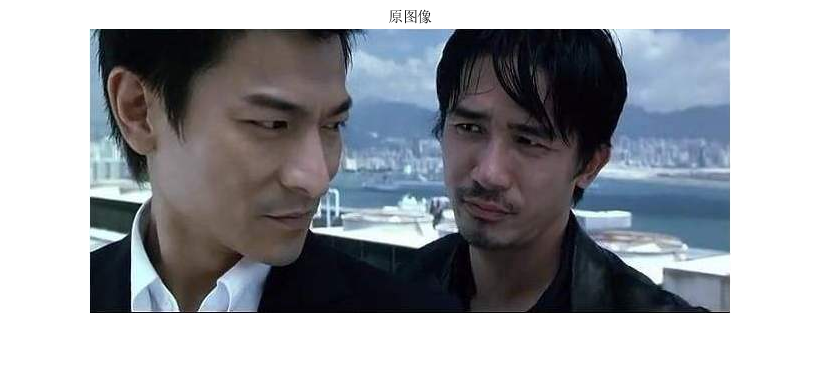

clc;
clear;
I=imread("07-刘德华.jpg");
I=im2double(I);
figure
imshow(I);
title("原图像");

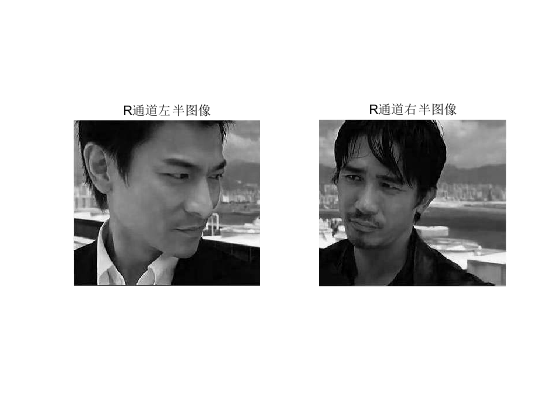

%取出图像的尺寸
I_size=size(I);
col=I_size(2);
%取出R通道
I_R=I(:,:,1);
%将R通道分为左右两半
I_Rl=I_R(:,1:col/2);
I_Rr=I_R(:,col/2+1:col);
%绘制图像
figure
subplot(1,2,1)
imshow(I_Rl);
title("R通道左半图像");
subplot(1,2,2)
imshow(I_Rr);
title("R通道右半图像");

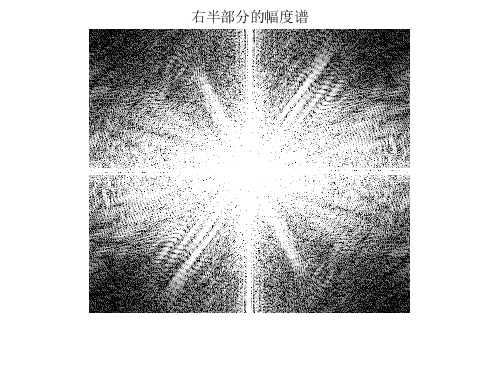

%对图像做二维傅里叶变换
Y_r=fft2(I_Rr);
Y_l=fft2(I_Rl);

%绘制左半部分的相位谱和右半部分的幅度谱
figure
mag=abs(fftshift(Y_r));%取幅度
imshow(log10(mag));
title('右半部分的幅度谱');

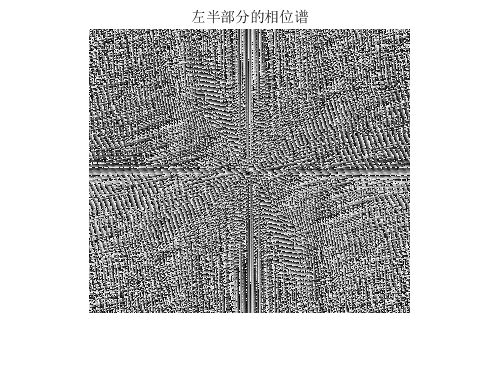

%绘制左图像相位谱
figure
phase=fftshift(angle(Y_l));%取相位
imshow(phase,[]);
title('左半部分的相位谱');

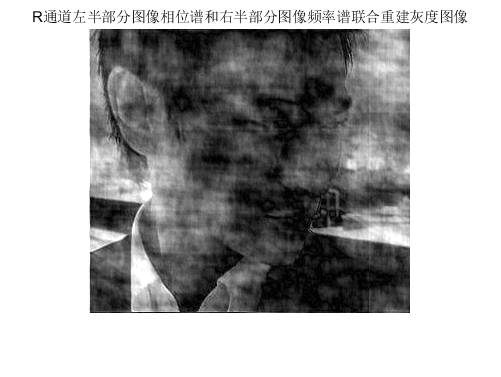

%合成图像
%将幅值乘以相位
Y_recons=mag.*exp(1j*phase);
%进行傅里叶逆变换
I_recons=abs(ifft2(Y_recons));
%绘制结果
figure
imshow(I_recons);
title("R通道左半部分图像相位谱和右半部分图像频率谱联合重建灰度图像");

%图片储存
imwrite(mag,'右半部图像的幅度谱.jpg','jpg');
imwrite(phase,'左半部图像的相位谱.jpg','jpg');
imwrite(I_recons,'合成的图像.jpg','jpg');